# Adaptively compensator tunning control

## Theoretical support

For a system $H_f(s) = \frac{K_f}{s\left(  T_fs + 1 \right)}$ discretized with Tustin method is equal with $H_f(z^{-1}) = \frac{b_0 + b_1z^{-1} + b_2z^{-2}}{1 + a_1z^{-1} + a_2z^{-2}}$ where:


$$K_f = \frac{4b_0}{(a_1 + 2)T_e} ;\;\;\;\;T_f = \frac{-T_ea_1}{2a_1 + 4}$$


Using Guillman - Truxall tunning method a compesator is obtain as follows:


$$H_{compesator}(s) = K_c\frac{T_Ds + 1}{T_Is + 1} = \frac{\omega_n}{2K_f\zeta}\frac{T_fs + 1}{\frac{1}{2\zeta\omega_n}s + 1}$$


If we discretize with zero order hold method we obtain:

$H_{compensator}(z^{-1}) = \frac{b_0 + b_1z^{-1}}{1 + a_1z^{-1}}$ where:


$$b_0 = K_c\frac{T_D}{T_I}\\
b_1 = K_c\left(1 - e^{-T_e/ T_I} - \frac{T_D}{T_I} \right)\\
a_1 = -e^{-T_e/ T_I}$$


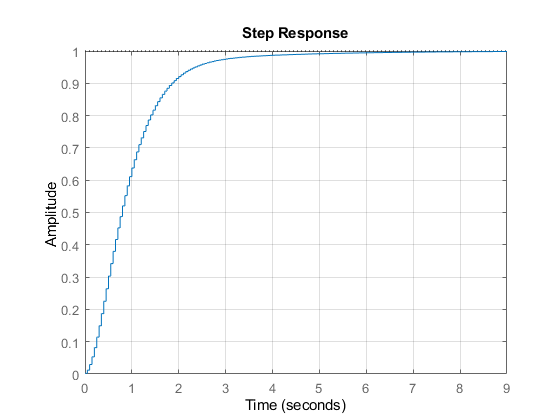

Kf = 2;
Tf = 2;
Te = 0.05;

Hf = tf(Kf, [Tf 1 0]);
wn = 2;
zeta = 1;
Hfd = c2d(Hf, Te, 'tustin');
[num, den] = tfdata(Hfd, 'v');
[num, den] = getDiscreteCompensator(den(2), num(1), Te, wn, zeta);
Hcd = tf(num, den, Te);
H0d = feedback(Hcd*Hfd, 1);
figure,
step(H0d); grid;

function [num, den] = getDiscreteCompensator(a1, b0, Te, wn, zeta)
    Tf = -Te*a1/(2*a1 + 4);
    Kf = 4*b0/((a1 + 2)*Te);
    Kc = wn/(2*Kf*zeta);
    Td = Tf;
    Ti = 1/(2*zeta*wn);
    
    bc0 = Kc*(Td/Ti);
    bc1 = Kc*(1 - exp(-Te/Ti) - Td/Ti);
    ac1 = -exp(-Te/Ti);
    num = [bc0 bc1];
    den = [1 ac1];
end